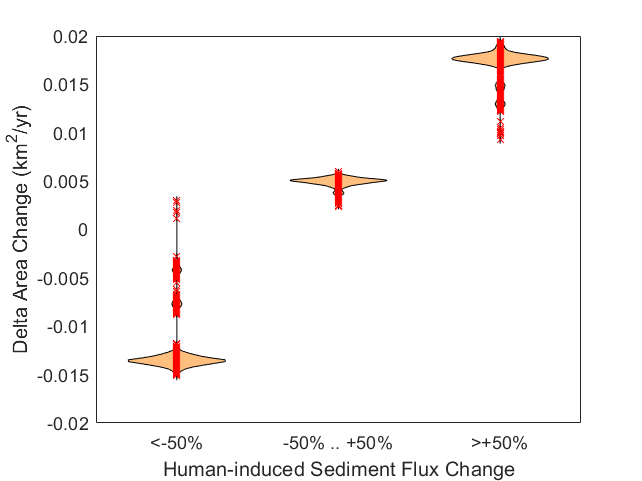

cd D:\DRIVE\SCIENCE_Projects\Nature2020\Codes\JaapNewFigure

%Original fixed
v1 = load('GlobalDeltaData_v1.mat','QRiver_dist','QRiver_prist','ee');
flux_ratio = v1.QRiver_dist./v1.QRiver_prist;
land = v1.ee.net_aqua;

bx = 0.5;
ca = [];
x = [];
b = [];

for ii=1:1000
    idx = randsample(length(flux_ratio),9762);
    x = land(idx);
    b = flux_ratio(idx);
    
    ca(ii,1) = mean(x(b<bx));
    ca(ii,2) = mean(x(b>bx & b<(2-bx)));
    ca(ii,3) = mean(x(b>(2-bx)));

end

xscatter = repmat([1:3], size(ca,1), 1);

clf

violin(ca,'mc','','medc','');
legend off
scatter(xscatter(:,1),ca(:,1),40,'xr')
hold on
scatter(xscatter(:,2),ca(:,2),40,'xr')
scatter(xscatter(:,3),ca(:,3),40,'xr')
hold off
xticklabels({'<-50%','-50% .. +50%','>+50%'})
xlabel('Human-induced Sediment Flux Change')
xticks([1 2 3]) 
xlim([0.5 3.5]) 
box on
ylabel('Delta Area Change (km^2/yr)')
ylim([-0.02 0.02]), %plot([0.5 3.5],[0 0],':k')

%saveas(gcf,'Figure1.svg')

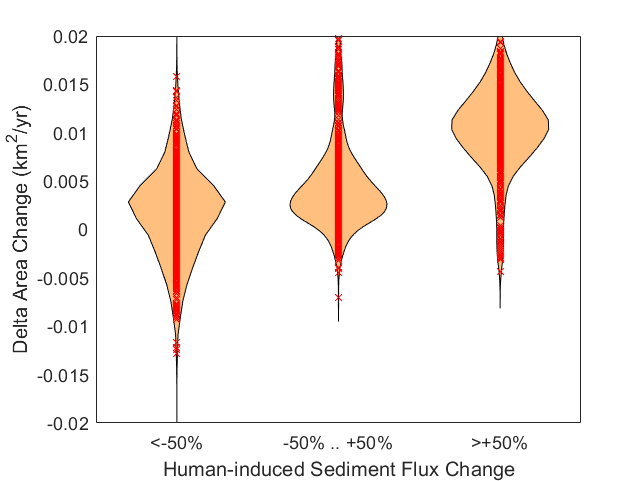

%Test 1 random draw 10%

v1 = load('GlobalDeltaData_v1.mat','QRiver_dist','QRiver_prist','ee');
flux_ratio = v1.QRiver_dist./v1.QRiver_prist;
land = v1.ee.net_aqua;

bx = 0.5;

for ii=1:1000
    idx = randsample(length(flux_ratio),1084);
    x = land(idx);
    b = flux_ratio(idx);
    
    ca_1000(ii,1) = mean(x(b<bx));
    ca_1000(ii,2) = mean(x(b>bx & b<(2-bx)));
    ca_1000(ii,3) = mean(x(b>(2-bx)));

end

xscatter = repmat([1:3], 1000, 1);

clf
violin(ca_1000,'mc','','medc','');
legend off
scatter(xscatter(:,1),ca_1000(:,1),40,'xr')
hold on
scatter(xscatter(:,2),ca_1000(:,2),40,'xr')
scatter(xscatter(:,3),ca_1000(:,3),40,'xr')
hold off
xticklabels({'<-50%','-50% .. +50%','>+50%'})
xlabel('Human-induced Sediment Flux Change')
xticks([1 2 3]) 
xlim([0.5 3.5]) 
box on
ylabel('Delta Area Change (km^2/yr)')
ylim([-0.02 0.02]), %plot([0.5 3.5],[0 0],':k')

%saveas(gcf,'Figure1.svg')


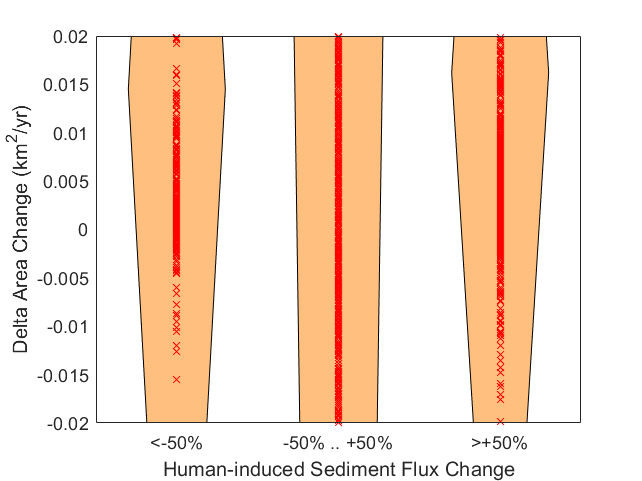

%Use original data
bx = 0.5;
%ca = [];
x = [];
b = [];


x = land;
b = flux_ratio;

decrease = x(b<bx);
stable = x(b>bx & b<(2-bx));
increase = x(b>(2-bx));
C = {decrease stable increase};


xscatter = repmat([1:3], size(ca,1), 1);

clf
violin(C,'mc','','medc','');
legend off
scatter(ones(size(decrease)), decrease,40,'xr')
hold on
scatter(ones(size(stable)).*2, stable,40,'xr')
scatter(ones(size(increase)).*3, increase,40,'xr')
hold off
xticklabels({'<-50%','-50% .. +50%','>+50%'})
xlabel('Human-induced Sediment Flux Change')
xticks([1 2 3]) 
xlim([0.5 3.5]) 
box on
ylabel('Delta Area Change (km^2/yr)')
ylim([-0.02 0.02]), %plot([0.5 3.5],[0 0],':k')

%saveas(gcf,'Figure1.svg')

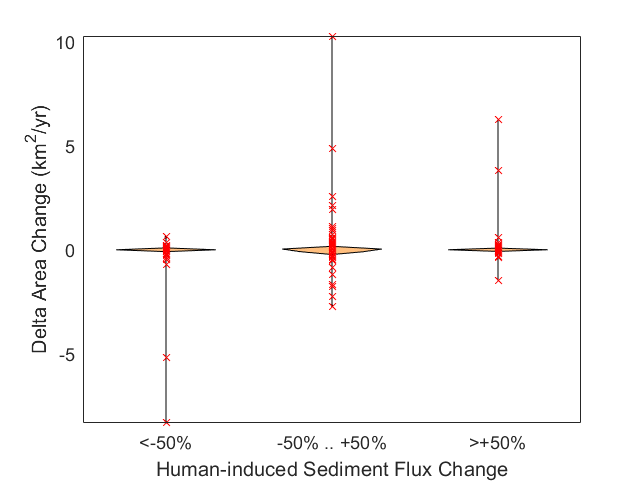

%Maximum free axis
bx = 0.5;
%ca = [];
x = [];
b = [];


x = land;
b = flux_ratio;

decrease = x(b<bx);
stable = x(b>bx & b<(2-bx));
increase = x(b>(2-bx));
C = {decrease stable increase};


xscatter = repmat([1:3], size(ca,1), 1);

clf
violin(C,'mc','','medc','');
legend off
scatter(ones(size(decrease)), decrease,40,'xr')
hold on
scatter(ones(size(stable)).*2, stable,40,'xr')
scatter(ones(size(increase)).*3, increase,40,'xr')
hold off
xticklabels({'<-50%','-50% .. +50%','>+50%'})
xlabel('Human-induced Sediment Flux Change')
xticks([1 2 3]) 
xlim([0.5 3.5]) 
box on
ylabel('Delta Area Change (km^2/yr)')

%ylim([-0.02 0.02]), %plot([0.5 3.5],[0 0],':k')
%saveas(gcf,'Figure1.svg')

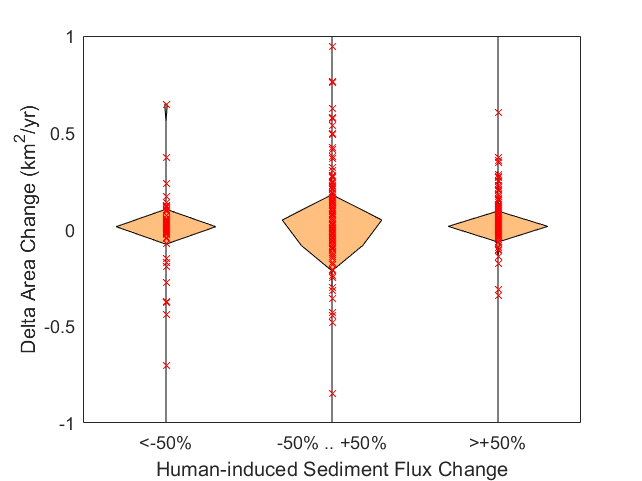

%Maximum free axis
bx = 0.5;
%ca = [];
x = [];
b = [];


x = land;
b = flux_ratio;

decrease = x(b<bx);
stable = x(b>bx & b<(2-bx));
increase = x(b>(2-bx));
C = {decrease stable increase};


xscatter = repmat([1:3], size(ca,1), 1);

clf
violin(C,'mc','','medc','');
legend off
scatter(ones(size(decrease)), decrease,40,'xr')
hold on
scatter(ones(size(stable)).*2, stable,40,'xr')
scatter(ones(size(increase)).*3, increase,40,'xr')
hold off
xticklabels({'<-50%','-50% .. +50%','>+50%'})
xlabel('Human-induced Sediment Flux Change')
xticks([1 2 3]) 
xlim([0.5 3.5]) 
box on
ylabel('Delta Area Change (km^2/yr)')
ylim([-1 1]), %plot([0.5 3.5],[0 0],':k')

%saveas(gcf,'Figure1.svg')



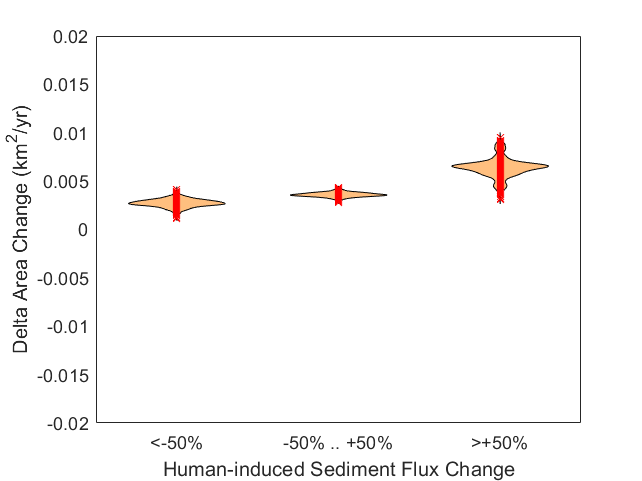

%Threshold 1
v1 = load('GlobalDeltaData_v1.mat','QRiver_dist','QRiver_prist','ee');
flux_ratio = v1.QRiver_dist./v1.QRiver_prist;
land = v1.ee.net_aqua;
land2 = land (land < 3);
land3 = land2 (land2 > -3);

bx = 0.5;
ca2 = [];
x = [];
b = [];

for ii=1:1000
    idx = randsample(length(land3),9762);
    x = land3(idx);
    b = flux_ratio(idx);
    
    ca2(ii,1) = mean(x(b<bx));
    ca2(ii,2) = mean(x(b>bx & b<(2-bx)));
    ca2(ii,3) = mean(x(b>(2-bx)));

end

xscatter = repmat([1:3], size(ca2,1), 1);

clf
violin(ca2,'mc','','medc','');
legend off
scatter(xscatter(:,1),ca2(:,1),40,'xr')
hold on
scatter(xscatter(:,2),ca2(:,2),40,'xr')
scatter(xscatter(:,3),ca2(:,3),40,'xr')
hold off
xticklabels({'<-50%','-50% .. +50%','>+50%'})
xlabel('Human-induced Sediment Flux Change')
xticks([1 2 3]) 
xlim([0.5 3.5]) 
box on
ylabel('Delta Area Change (km^2/yr)')
ylim([-0.02 0.02]), %plot([0.5 3.5],[0 0],':k')

%saveas(gcf,'Figure1.svg')

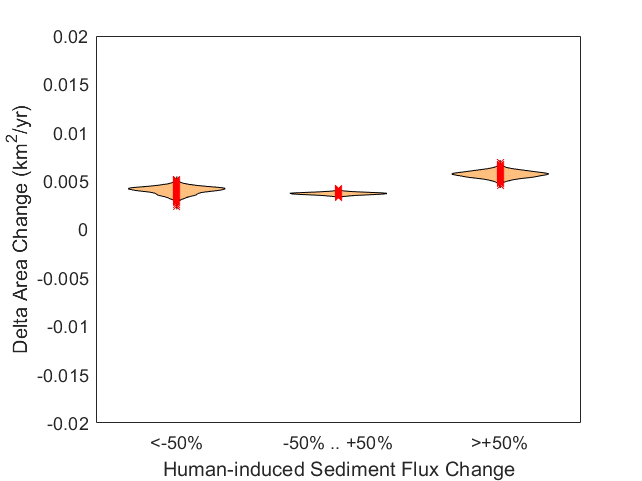


%threshold 2
v1 = load('GlobalDeltaData_v1.mat','QRiver_dist','QRiver_prist','ee');
flux_ratio = v1.QRiver_dist./v1.QRiver_prist;
land = v1.ee.net_aqua;
land4 = land (land < 1);
land5 = land4 (land4 > -1);

bx = 0.5;
ca3 = [];
x = [];
b = [];

for ii=1:1000
    idx = randsample(length(land5),9762);
    x = land5(idx);
    b = flux_ratio(idx);
    
    ca3(ii,1) = mean(x(b<bx));
    ca3(ii,2) = mean(x(b>bx & b<(2-bx)));
    ca3(ii,3) = mean(x(b>(2-bx)));

end

xscatter = repmat([1:3], size(ca3,1), 1);

clf
violin(ca3,'mc','','medc','');
legend off
scatter(xscatter(:,1),ca3(:,1),40,'xr')
hold on
scatter(xscatter(:,2),ca3(:,2),40,'xr')
scatter(xscatter(:,3),ca3(:,3),40,'xr')
hold off
xticklabels({'<-50%','-50% .. +50%','>+50%'})
xlabel('Human-induced Sediment Flux Change')
xticks([1 2 3]) 
xlim([0.5 3.5]) 
box on
ylabel('Delta Area Change (km^2/yr)')
ylim([-0.02 0.02]), %plot([0.5 3.5],[0 0],':k')

%saveas(gcf,'Figure1.svg')

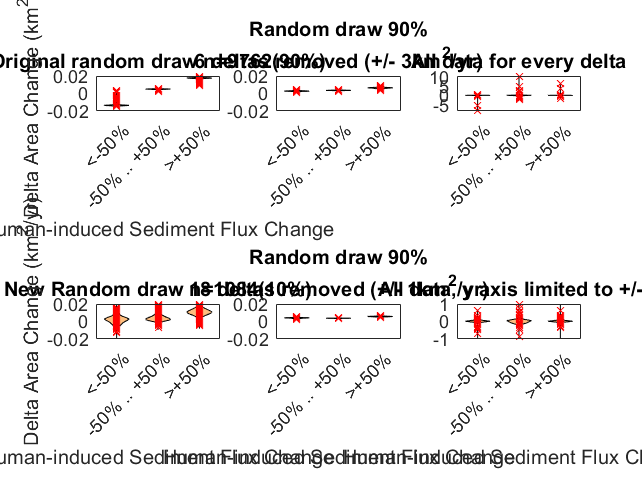

clf
figure
subplot(2,3,1)
violin(ca,'mc','','medc','');
legend off
scatter(xscatter(:,1),ca(:,1),40,'xr')
hold on
scatter(xscatter(:,2),ca(:,2),40,'xr')
scatter(xscatter(:,3),ca(:,3),40,'xr')
hold off
xticklabels({'<-50%','-50% .. +50%','>+50%'})
xlabel('Human-induced Sediment Flux Change')
xticks([1 2 3]) 
xlim([0.5 3.5]) 
box on
ylabel('Delta Area Change (km^2/yr)')
ylim([-0.02 0.02]), %plot([0.5 3.5],[0 0],':k')

title 'Original random draw n=9762(90%)'

subplot(2,3,4)
violin(ca_1000,'mc','','medc','');
legend off
scatter(xscatter(:,1),ca_1000(:,1),40,'xr')
hold on
scatter(xscatter(:,2),ca_1000(:,2),40,'xr')
scatter(xscatter(:,3),ca_1000(:,3),40,'xr')
hold off
xticklabels({'<-50%','-50% .. +50%','>+50%'})
xlabel('Human-induced Sediment Flux Change')
xticks([1 2 3]) 
xlim([0.5 3.5]) 
box on
ylabel('Delta Area Change (km^2/yr)')
ylim([-0.02 0.02]), %plot([0.5 3.5],[0 0],':k')
%saveas(gcf,'Figure1.svg')
title 'New Random draw n=1084(10%)'

subplot(2,3,2)
violin(ca2,'mc','','medc','');
legend off
scatter(xscatter(:,1),ca2(:,1),40,'xr')
hold on
scatter(xscatter(:,2),ca2(:,2),40,'xr')
scatter(xscatter(:,3),ca2(:,3),40,'xr')
hold off
xticklabels({'<-50%','-50% .. +50%','>+50%'})
%xlabel('Human-induced Sediment Flux Change')
xticks([1 2 3]) 
xlim([0.5 3.5]) 
box on
%ylabel('Delta Area Change (km^2/yr)')
ylim([-0.02 0.02]), %plot([0.5 3.5],[0 0],':k')
%saveas(gcf,'Figure1.svg')
title({'Random draw 90%','6 deltas removed (+/- 3km^2/yr)'}) 

subplot(2,3,5)
violin(ca3,'mc','','medc','');
legend off
scatter(xscatter(:,1),ca3(:,1),40,'xr')
hold on
scatter(xscatter(:,2),ca3(:,2),40,'xr')
scatter(xscatter(:,3),ca3(:,3),40,'xr')
hold off
xticklabels({'<-50%','-50% .. +50%','>+50%'})
xlabel('Human-induced Sediment Flux Change')
xticks([1 2 3]) 
xlim([0.5 3.5]) 
box on
%ylabel('Delta Area Change (km^2/yr)')
ylim([-0.02 0.02]), %plot([0.5 3.5],[0 0],':k')
%saveas(gcf,'Figure1.svg')
%title 'Random draw 90%'
%subtitle '18 extreme deltas removed (+/- 1km^2/yr)'
title({'Random draw 90%','18 deltas removed (+/- 1km^2/yr)'}) 

subplot(2,3,3)
violin(C,'mc','','medc','');
legend off
scatter(ones(size(decrease)), decrease,40,'xr')
hold on
scatter(ones(size(stable)).*2, stable,40,'xr')
scatter(ones(size(increase)).*3, increase,40,'xr')
hold off
xticklabels({'<-50%','-50% .. +50%','>+50%'})
%xlabel('Human-induced Sediment Flux Change')
xticks([1 2 3]) 
xlim([0.5 3.5]) 
box on
%ylabel('Delta Area Change (km^2/yr)')
%ylim([-0.02 0.02]), %plot([0.5 3.5],[0 0],':k')
%saveas(gcf,'Figure1.svg')
title 'All data for every delta'

subplot(2,3,6)
violin(C,'mc','','medc','');
legend off
scatter(ones(size(decrease)), decrease,40,'xr')
hold on
scatter(ones(size(stable)).*2, stable,40,'xr')
scatter(ones(size(increase)).*3, increase,40,'xr')
hold off
xticklabels({'<-50%','-50% .. +50%','>+50%'})
xlabel('Human-induced Sediment Flux Change')
xticks([1 2 3]) 
xlim([0.5 3.5]) 
box on
%ylabel('Delta Area Change (km^2/yr)')
ylim([-1 1]), %plot([0.5 3.5],[0 0],':k')
%saveas(gcf,'Figure1.svg')
title 'All data, y axis limited to +/- 1'